a = 100;
R = 1000;
theta = -pi/2:pi/12:pi/2

theta =    -1.5708   -1.3090   -1.0472   -0.7854   -0.5236   -0.2618         0    0.2618    0.5236    0.7854    1.0472    1.3090    1.5708


g = (R^2+(a/2).^2).^2/(a.*R)

g = 1.0050e+07

V4 = sqrt(abs(sin(theta)./(sin(theta)-g)))

V4 = 1.0e-03 *

    0.3154    0.3100    0.2935    0.2653    0.2230    0.1605         0    0.1605    0.2230    0.2653    0.2935    0.3100    0.3154


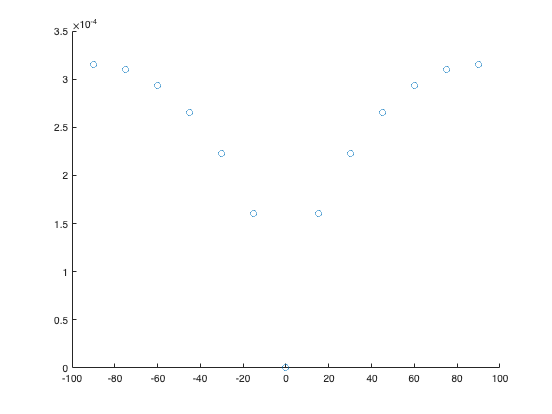

scatter(theta*180/pi,V4)

for A = a
    Delta_P = abs((2.*A.*R.*sin(theta))./(A^2*R^2.*sin(theta).^2-R^4+(R^2*A^2)/2+A^4/16));

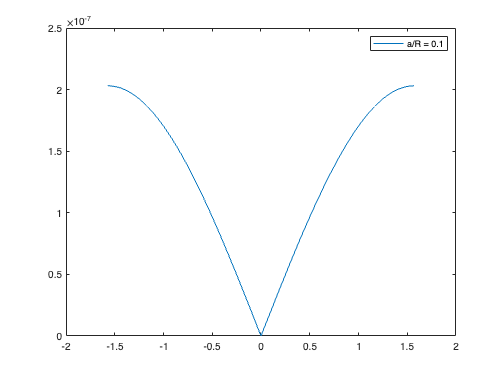

    plot(theta,Delta_P,'DisplayName','a/R = '+string(A/R))

    legend
    hold on
end    
hold off

a = 10:30:400;
R = 1000;
theta = -pi/2:0.001:pi/2;


for A = a
    Delta_P = abs((2.*A.*R.*sin(theta))./(A^2*R^2.*sin(theta).^2-R^4+(R^2*A^2)/2+A^4/16));

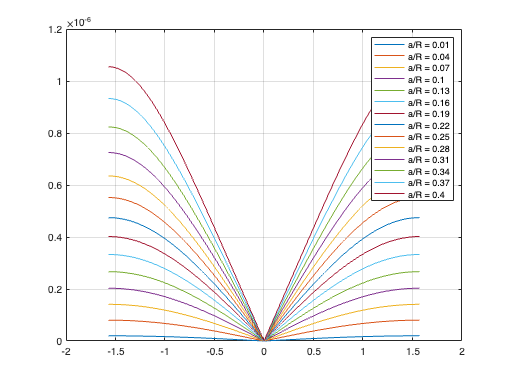

    plot(theta,Delta_P,'DisplayName','a/R = '+string(A/R))

    legend
    hold on
    grid on
end 

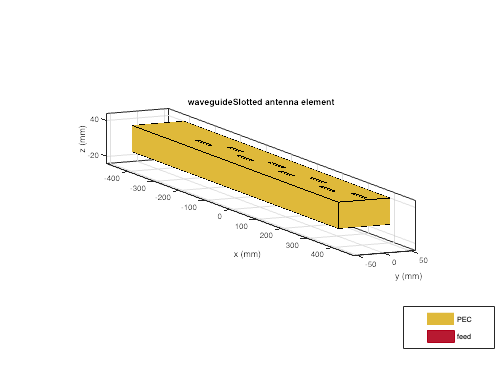

 ant = waveguideSlotted('Length',806e-3,'Width',94e-3, 'NumSlots',8,...
      'Height',44e-3,'Slot',antenna.Rectangle('Length',53e-3,'Width',6.5e-3),'SlotToTop',40.3e-3,...
      'SlotSpacing',80.6e-3,'SlotOffset',10e-3,'FeedHeight',31e-3, ...
      'FeedOffset',[-362.7e-3 0],'FeedWidth',2e-3);
show (ant) 

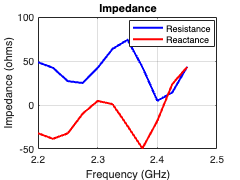

ans = 3

freq = 2.2e9:1e9:10.2e9;
figure;
impedance(ant,freq)

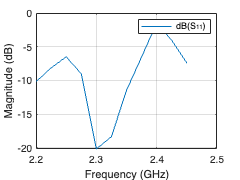

s = sparameters(ant,freq);
figure;
rfplot(s);

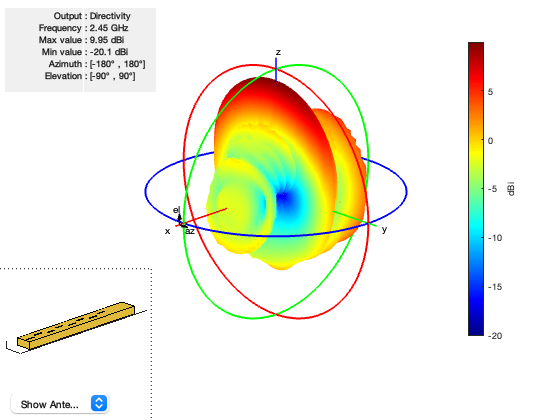

pattern(ant, 2.45e9)